# Visualization of $C_p
$ with respect to chord position

Let's first load our data

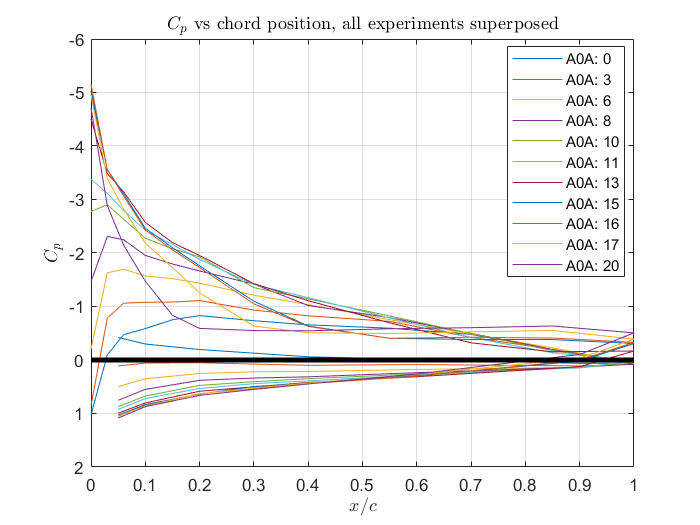

load('Data\Calibrated_Airfoil_Pressure_Pa_Interpolated_Coeffs.mat')
load('Data\calibrated_manometer_data_Pa.mat')
load('Code\location.mat')
h = figure;
axis tight manual % this ensures that getframe() returns a consistent size
gif = 'testAnimated.gif';
q = 1/2 * 1.225 * 29.214^2;

plot(location, p0/q)
hold on
plot(location, p3/q)
plot(location, p6/q)
plot(location, p8/q)
plot(location, p10/q)
plot(location, p11/q)
plot(location, p13/q)
plot(location, p15/q)
plot(location, p16/q)
plot(location, p17/q)
plot(location, p20/q)
plot(linspace(0,1,11),zeros(1,11), '-k','lineWidth',3)
hold off
set(gca, 'YDir','reverse')
grid on

xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title(['$C_p$ vs chord position, ' ...
    'all experiments superposed'], ...
      'interpreter', 'latex')
legend('A0A: 0', 'A0A: 3', 'A0A: 6', ...
        'A0A: 8', 'A0A: 10', 'A0A: 11', ...
        'A0A: 13', 'A0A: 15', 'A0A: 16', ...
        'A0A: 17','A0A: 20','Location',"best")

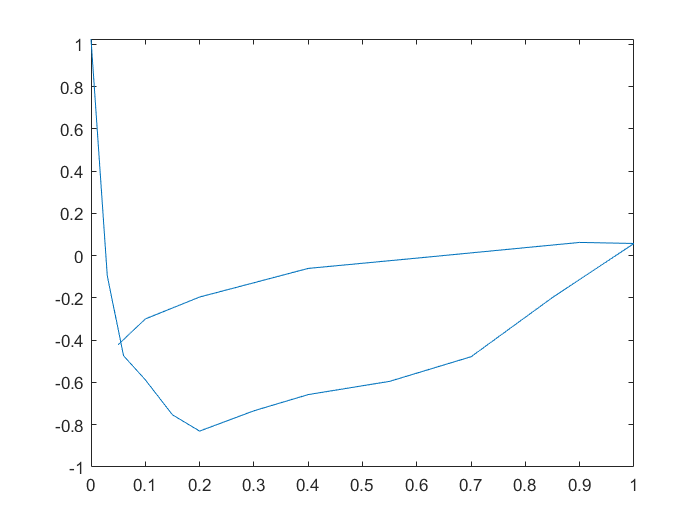

plot(location, p0/q);
hold on

filename = 'XFOIL Analysis/clark_y_0.cp';
A = importdata(filename,' ', 3);
plot(A.data(:,1), A.data(:, 3))

Reference to non-existent field 'data'.

plot(location, airfoil_manometer(1, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 0 $^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")

frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif', 'Loopcount',inf); 

plot(location, p3/q);
filename = 'XFOIL Analysis/clark_y_3.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(2, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 3 $^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")

frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 

plot(location, p6/q);
filename = 'XFOIL Analysis/clark_y_6.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(3, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 6$^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")


frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 

plot(location, p8/q);
filename = 'XFOIL Analysis/clark_y_8.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(4, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 8$^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")

frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 

plot(location, p10/q);
filename = 'XFOIL Analysis/clark_y_10.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(5, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 10$^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")

frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 

plot(location, p11/q);
filename = 'XFOIL Analysis/clark_y_11.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(6, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 11$^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")

frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 

plot(location, p13/q);
filename = 'XFOIL Analysis/clark_y_13.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(7, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 13$^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")

frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 

plot(location, p15/q);
filename = 'XFOIL Analysis/clark_y_15.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(8, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 15$^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")

frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 

plot(location, p16/q);
filename = 'XFOIL Analysis/clark_y_16.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(9, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 16$^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")

frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 

plot(location, p17/q);
filename = 'XFOIL Analysis/clark_y_17.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(10, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 17$^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")
frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 

plot(location, p20/q);
filename = 'XFOIL Analysis/clark_y_20.cp';
A = importdata(filename,' ', 3);
hold on
plot(A.data(:,1), A.data(:, 3))
plot(location, airfoil_manometer(11, :)/q)
hold off
set(gca, 'YDir','reverse')
xlim([0 1])
xlabel('$x/c$', "interpreter", "latex")
ylabel('$C_p$',"interpreter",'latex')
title('$C_p$ vs chord position, AOA = 20$^{\circ}$', ...
      'interpreter', 'latex')
legend('Experiment Data', 'XFOIL Data','Manometer', ...
    'Location',"best")
frame = getframe(h); 
im = frame2im(frame); 
[imind,cm] = rgb2ind(im,256);
imwrite(imind,cm,gif,'gif','WriteMode','append'); 